# Creating Filters in Swan

## Introduction

In these tutorial files, you will learn how to use the various modules of Swan in order to generate your own FEM and Topology Optimization simulations. In each tutorial, a single building block will be analyzed, with some examples to make it easier. If you have any questions, feel free to create a new issue in the GitHub repository.

## Preliminars

In this tutorial we will deal with Filters, which are crucial tools to control the *gray* regions of density fields or avoid checkerboarding problems during simulations. Given any function defined on our domain, Filters basically build a Finite Element Function based in the input function and smoothing it.

Before starting bulding our own filters, let's begin with some preliminars. First, we need a mesh on which the *given* (or input) function will be projected and filtered. Consider the following discretization of a [0,1]x[0,1] domain:

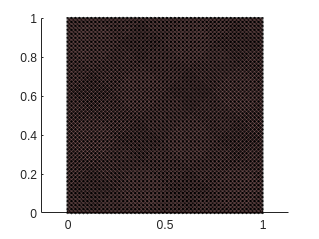

x1 = linspace(0,1,50);
x2 = linspace(0,1,50);

[xv,yv] = meshgrid(x1,x2);

[F,V] = mesh2tri(xv,yv,zeros(size(xv)),'x');

m.coord  = V(:,1:2);
m.connec = F;
mesh = Mesh(m);

figure()
mesh.plot()

Moreover, we need a *given *function. As an example, we are going to create a Characteristic Function, which will be defined on previous [0,1]x[0,1] domain.

s.fHandle = @(x) 1-heaviside((x(1,:,:)-0.5).^2+(x(2,:,:)-0.5).^2-0.3.^2);
s.ndimf   = 1; % Number of dimensions of fHandle image. In this case is a scalar function.
s.mesh    = mesh;
fun       = AnalyticalFunction(s);

We can see that previous function returns 0 everywhere except on a disc of height z=1, centered on (0.5,0.5) and radius 0.3. See some computations:

x=[0.5;0.5];
fx = num2str(s.fHandle(x));
fprintf(['f(0.5,0.5)=',fx])

f(0.5,0.5)=1


x=[0.2;0.2];
fx = num2str(s.fHandle(x));
fprintf(['f(0.2,0.2)=',fx])

f(0.2,0.2)=0

Lastly, we can see how this characteristic function would look like by projecting it to a P0 FE function:

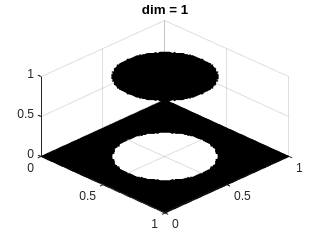

fP0 = fun.project('P0');
fP0.plot()
view(45,45)

## Density filters

### P1 Filter

Let's start now creating our first filter: P1 Density. We will do so with the following lines

ss.designVarType = 'Density';
ss.filterType    = 'P1';
ss.mesh          = mesh;
filter           = Filter.create(ss);

Now we can obtain our first P1 function of our characteristic function by means of the following filter public command. Besides, we will need to include a quadrature to integrate the input function. The idea is to use an enough high order quadrature concerning the linearity of our input function. In this case, it will be enough to just use a linear order.

fP1 = filter.getP1Function(fun,'LINEAR');

And of course we can plot it

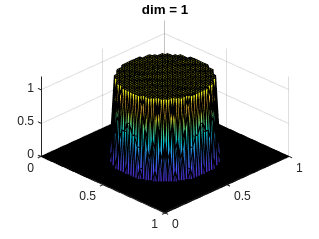

fP1.plot()
view(45,45)

## Miss anything?

Feel free to create a new Issue in Swan's GitHub repository with any questions or doubts you may have. We will get back to you as soon as possible!